% Limpiar el espacio de trabajo, la ventana de comandos y cerrar figuras
clear;    
clc;     
close all;

% Definir los parámetros simbólicos
syms theta alpha1 beta1 gamma1 mu1 alpha2 beta2 gamma2 mu2 alpha3 beta3 tau x1 x2 x3 C
assume(theta >=0)

## MATRIZ JACOBIANA

% Definir las ecuaciones
f1 = (alpha1 * x1 * (C - x1 - x2 - x3)) / (1 + gamma1 * x3) - x1 * (beta1 + mu1 * x3-theta);
f2 = (alpha2 * x2 * (C - x1 - x2 - x3) * (1 + tau * x1)) / (1 + x3 * gamma2) - x2 * (beta2 + mu2 * x3);
f3 = alpha3 * x3 * (C - x1 - x2 - x3) - beta3 * x3;

% Definir el sistema de ecuaciones
F = [f1; f2; f3];

% Definir las variables
vars = [x1, x2, x3];


%% Calcular la matriz Jacobiana

J = jacobian(F, vars)

$$J = \begin{array}{l} \left(\begin{array}{ccc} \theta -\beta_{1}-\mu_{1}\,x_{3}-\frac{\alpha_{1}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{1}\,x_{3}+1}-\sigma_{2} & -\sigma_{2} & \frac{\alpha_{1}\,\gamma_{1}\,x_{1}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{{\left(\gamma_{1}\,x_{3}+1\right)}^{2}}-\sigma_{2}-\mu_{1}\,x_{1}\\ -\sigma_{1}-\frac{\alpha_{2}\,\tau \,x_{2}\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{2}\,x_{3}+1} & -\beta_{2}-\mu_{2}\,x_{3}-\frac{\alpha_{2}\,\left(\tau \,x_{1}+1\right)\,\left(x_{1}-C+x_{2}+x_{3}\right)}{\gamma_{2}\,x_{3}+1}-\sigma_{1} & \frac{\alpha_{2}\,\gamma_{2}\,x_{2}\,\left(\tau \,x_{1}+1\right)\,\left(x_{1}-C+x_{2}+x_{3}\right)}{{\left(\gamma_{2}\,x_{3}+1\right)}^{2}}-\sigma_{1}-\mu_{2}\,x_{2}\\ -\alpha_{3}\,x_{3} & -\alpha_{3}\,x_{3} & -\beta_{3}-\alpha_{3}\,\left(x_{1}-C+x_{2}+x_{3}\right)-\alpha_{3}\,x_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\alpha_{2}\,x_{2}\,\left(\tau \,x_{1}+1\right)}{\gamma_{2}\,x_{3}+1}\\ \sigma_{2}=\frac{\alpha_{1}\,x_{1}}{\gamma_{1}\,x_{3}+1} \end{array}$$


% Definir los valores de los parámetros
alpha1_val = 0.00137;
beta1_val = 0.07;
gamma1_val = 0.01;
mu1_val = 0.01;
alpha2_val = 0.0011;
beta2_val = 0.29;
gamma2_val = 0.01;
mu2_val = 0.01;
alpha3_val = 0.001;
beta3_val = 0.1;
tau_val = 0.0995;
C_val = 146.9;


% Modificar
%theta = 0.5;

sigma1 = 1/(2*gamma2_val*mu2_val)*( -(beta2_val*gamma2_val + mu2_val) + sqrt( (beta2_val*gamma2_val-mu2_val)^2 + (4*gamma2_val*mu2_val*alpha2_val*beta3_val)/alpha3_val ) );
sigma2_suma = 1/(2*gamma1_val*mu1_val)*( -((beta1_val-theta)*gamma1_val + mu1_val) + sqrt( ((beta1_val-theta)*gamma1_val-mu1_val)^2 + (4*gamma1_val*mu1_val*alpha1_val*beta3_val)/alpha3_val ) );
sigma2_resta = 1/(2*gamma1_val*mu1_val)*( -((beta1_val-theta)*gamma1_val + mu1_val) - sqrt( ((beta1_val-theta)*gamma1_val-mu1_val)^2 + (4*gamma1_val*mu1_val*alpha1_val*beta3_val)/alpha3_val ) );
M_suma = beta2_val + mu2_val*sigma2_suma;
M_resta = beta2_val + mu2_val*sigma2_resta;
N_suma = gamma2_val*sigma2_suma + 1;
N_resta = gamma2_val*sigma2_resta + 1;
P = alpha2_val*(beta3_val/alpha3_val);


% Definir el valor de punto
punto = "p5";

if punto == "p0"
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p1"
    x1_formula = 0;
    x2_formula = 0;
    x3_formula = C_val - beta3_val/alpha3_val;
elseif punto == "p2"
    x1_formula = 0;
    x2_formula = C_val - beta2_val/alpha2_val;
    x3_formula = 0;
elseif punto == "p3"
    x1_formula = 0;
    x2_formula = C_val - sigma1 - beta3_val/alpha3_val;
    x3_formula = sigma1;
elseif punto == "p4"
    x1_formula = C_val - (beta1_val-theta)/alpha1_val;
    x2_formula = 0;
    x3_formula = 0;
elseif punto == "p5"
    x1_formula = C_val - sigma2_suma - beta3_val / alpha3_val;
    x2_formula = 0;
    x3_formula = sigma2_suma;
elseif punto == "p6"
    x1_formula = C_val - sigma2_resta - beta3_val/alpha3_val;
    x2_formula = 0;
    x3_formula = sigma2_resta;
elseif punto == "p7"
    x1_formula = (alpha1_val*beta2_val-alpha2_val*(beta1_val-theta))/(alpha2_val*(beta1_val-theta)*tau_val);
    x2_formula = C_val - x1_formula - (beta1_val-theta)/alpha1_val;
    x3_formula = 0;
elseif punto == "p8"
    x1_formula = alpha3_val*(M_suma*N_suma-P)/(alpha2_val*tau_val*beta3_val);
    x2_formula = C_val - x1_formula - sigma2_suma - beta3_val/alpha3_val;
    x3_formula = sigma2_suma;
else
    x1_formula = alpha3_val*(M_resta*N_resta-P)/(alpha2_val*tau_val*beta3_val);
    x2_formula = C_val - x1_formula - sigma2_resta - beta3_val/alpha3_val;
    x3_formula = sigma2_resta;
end


% Verificar
f1 = (alpha1_val * x1_formula * (C_val - x1_formula - x2_formula - x3_formula)) / (1 + gamma1_val * x3_formula) - x1_formula * (beta1_val + mu1_val * x3_formula - theta);
f2 = (alpha2_val * x2_formula * (C_val - x1_formula - x2_formula - x3_formula) * (1 + tau_val * x1_formula)) / (1 + x3_formula * gamma2_val) - x2_formula * (beta2_val + mu2_val * x3_formula);
f3 = alpha3_val * x3_formula * (C_val - x1_formula - x2_formula - x3_formula) - beta3_val * x3_formula;

% Crear la lista de parámetros sin incluir eta
param_vals = [alpha1, beta1, gamma1, mu1, alpha2, beta2, gamma2, mu2, alpha3, beta3, tau, C, x1, x2, x3];
param_subs = [alpha1_val, beta1_val, gamma1_val, mu1_val, alpha2_val, beta2_val, gamma2_val, mu2_val, alpha3_val, beta3_val, tau_val, C_val, x1_formula, x2_formula, x3_formula];

% Evaluar la matriz Jacobiana con los valores de los parámetros excepto eta
J_simb = subs(J, param_vals, param_subs)

$$J\_simb = \begin{array}{l} \left(\begin{array}{ccc} \frac{\theta }{2}+\frac{\sigma_{3}}{100000\,\sigma_{1}}+\frac{137}{1000\,\sigma_{1}}-50\,\sigma_{4}+\frac{93}{200} & \frac{\sigma_{3}}{100000\,\sigma_{1}} & \frac{\theta }{2}+\frac{\sigma_{3}}{100000\,\sigma_{1}}+\frac{\sigma_{3}}{100000\,{\sigma_{1}}^{2}}+50\,\sigma_{4}-\frac{251}{250}\\ 0 & \frac{49}{200}-\frac{11\,\left(\frac{199\,\theta }{40}+\frac{995\,\sigma_{4}}{2}-\frac{54949}{5000}\right)}{100\,\sigma_{1}}-50\,\sigma_{4}-\frac{\theta }{2} & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\theta }{2}+50\,\sigma_{4}+\frac{93}{200}\\ \sigma_{2}=\frac{107}{2000}-5\,\sigma_{4}-\frac{\theta }{20}\\ \sigma_{3}=137\,\left(50\,\theta +5000\,\sigma_{4}-\frac{502}{5}\right)\\ \sigma_{4}=\sqrt{{\left(\frac{\theta }{100}+\frac{93}{10000}\right)}^{2}+\frac{8087052601914267}{147573952589676412928}} \end{array}$$

## VALORES PROPIOS

% Calcular los valores propios simbólicos
valores_propios_simb = eig(J_simb);

% Obtener los valores propios como un vector de expresiones simbólicas
valores_propios_simplificados = simplify(valores_propios_simb);

% Mostrar los valores propios simplificados
disp('Valores propios simplificados:');

Valores propios simplificados:


disp(valores_propios_simplificados);

## Graficos

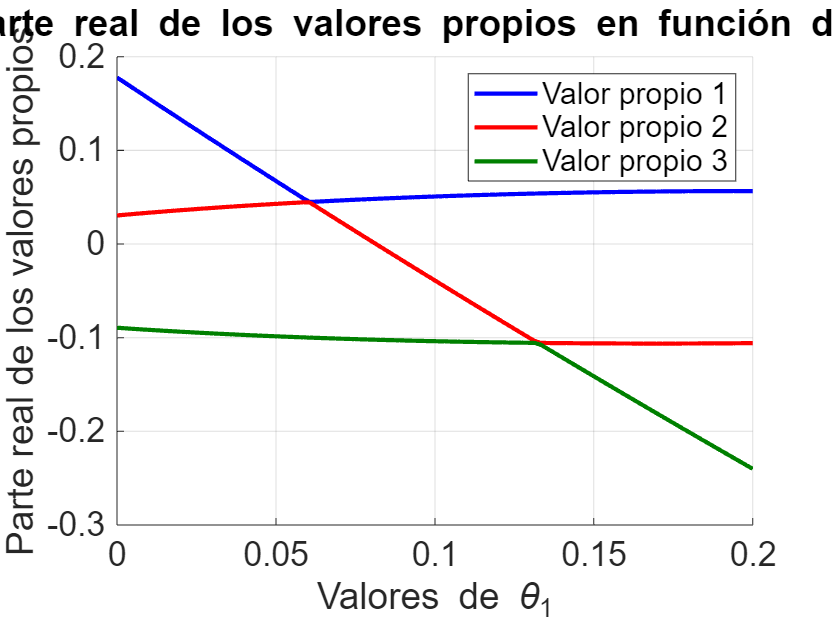

% Inicializar el rango de valores para theta1
theta_values = linspace(0, 0.2, 100);
valores_propios_evaluados_num = zeros(length(theta_values), 3); % Matriz para almacenar valores propios

% Evaluar los valores propios para cada theta1
for j = 1:length(theta_values)
    theta_actual = theta_values(j);
    
    % Evaluar los valores propios con el eta actual
    valores_propios_evaluados = subs(valores_propios_simplificados, theta, theta_actual);
    
    % Sustituir todos los parámetros simbólicos con sus valores numéricos
    valores_propios_evaluados_num(j, :) = double(subs(valores_propios_evaluados, param_vals, param_subs));
end

% Graficar solo la parte real de los valores propios
figure;
hold on;
plot(theta_values, real(valores_propios_evaluados_num(:, 1)), 'b-', 'DisplayName', 'Valor propio 1','LineWidth', 2);
plot(theta_values, real(valores_propios_evaluados_num(:, 2)), 'r-', 'DisplayName', 'Valor propio 2','LineWidth', 2);
plot(theta_values, real(valores_propios_evaluados_num(:, 3)), 'color', [0, 0.5, 0] , 'DisplayName', 'Valor propio 3','LineWidth', 2);
xlabel('Valores de \theta_1', 'FontSize', 15);
ylabel('Parte real de los valores propios', 'FontSize', 15);
title('Parte real de los valores propios en función de \theta_1','FontSize', 16);
grid on;
legend show;

ax = gca;
ax.FontSize = 16;

hold off;

## Valores donde hay cambio de signo en valores pripios

% Detectar cambios de signo y guardar los intervalos
intervalos_theta = [];
for k = 1:length(theta_values)-1
    % Revisar si hay cambio de signo en cualquiera de los valores propios
    if (real(valores_propios_evaluados_num(k, 1)) * real(valores_propios_evaluados_num(k+1, 1)) < 0 ...
            || real(valores_propios_evaluados_num(k, 2)) * real(valores_propios_evaluados_num(k+1, 2)) < 0 ...
            || real(valores_propios_evaluados_num(k, 3)) * real(valores_propios_evaluados_num(k+1, 3)) < 0)
        
        % Guardar el intervalo donde ocurre el cambio de signo
        fprintf('Cambio de signo detectado entre theta_1 = %.4f y theta_1 = %.4f\n', theta_values(k), theta_values(k+1));
        intervalos_theta = [intervalos_theta; theta_values(k), theta_values(k+1)]; %#ok<AGROW>
    end
end

Cambio de signo detectado entre theta_1 = 0.0808 y theta_1 = 0.0828



% Mostrar los intervalos de cambio de signo identificados
disp('Intervalos donde se detectaron cambios de signo:');

Intervalos donde se detectaron cambios de signo:


disp(intervalos_theta);

    0.0808    0.0828




% Intentar resolver cada ecuación de valores propios == 0 dentro de los intervalos específicos
theta_criticos_encontrados = [];
for i = 1:size(intervalos_theta, 1)
    theta_start = intervalos_theta(i, 1);
    theta_end = intervalos_theta(i, 2);
    
    % Probar con varios puntos de inicio dentro del intervalo
    puntos_inicio = linspace(theta_start, theta_end, 5); % 5 puntos equiespaciados dentro del intervalo
    
    % Variable para almacenar soluciones dentro del intervalo
    theta_intervalo = [];
    
    for p = 1:length(puntos_inicio)
        % Usar cada punto como semilla inicial para vpasolve
        theta_midpoint = puntos_inicio(p);
        
        % Resolver cada valor propio dentro del intervalo
        theta_critico1 = vpasolve(valores_propios_simplificados(1) == 0, theta, theta_midpoint);
        theta_critico2 = vpasolve(valores_propios_simplificados(2) == 0, theta, theta_midpoint);
        theta_critico3 = vpasolve(valores_propios_simplificados(3) == 0, theta, theta_midpoint);
        
        % Concatenar los valores críticos encontrados en este subintervalo
        theta_criticos_intervalo = [theta_critico1; theta_critico2; theta_critico3];
        
        % Convertir los valores críticos a formato numérico
        theta_criticos_intervalo_numeric = double(theta_criticos_intervalo);
        
        % Filtrar solo valores finitos, reales y positivos de eta (considerando eta > 0)
        theta_filtrados = theta_criticos_intervalo_numeric(isfinite(theta_criticos_intervalo_numeric) & isreal(theta_criticos_intervalo_numeric) & (theta_criticos_intervalo_numeric > 0));
        
        % Agregar las soluciones de este subintervalo
        theta_intervalo = [theta_intervalo; theta_filtrados(:)];
    end
    
    % Agregar los valores críticos únicos de este intervalo a la lista general
    theta_criticos_encontrados = [theta_criticos_encontrados; unique(theta_intervalo)]; %#ok<AGROW>
end

% Ordenar los valores críticos de eta encontrados
theta_criticos_reales_sorted = sort(theta_criticos_encontrados);

% Crear los intervalos asegurando que 0 esté al principio y inf al final
intervalos_filtrados = [0; theta_criticos_reales_sorted(:); inf]; % Asegúrate de que los valores sean columna

% Comprobar el resultado
disp('Intervalos filtrados:');

Intervalos filtrados:


disp(intervalos_filtrados);

         0
    0.0815
       Inf



## REVISAR ESTABILDIAD

%% Revisar estabilidad en cada intervalo de eta
% Clasificar la estabilidad en cada intervalo
for i = 1:length(intervalos_filtrados)-1
    % Calcular el eta medio en cada intervalo
    theta_medio = (intervalos_filtrados(i) + intervalos_filtrados(i+1)) / 2;

    % Evaluar los valores propios con eta_medio
    valores_propios_evaluados = subs(valores_propios_simplificados, theta, theta_medio);

    % Sustituir todos los parámetros simbólicos con sus valores numéricos
    valores_propios_evaluados_num = double(subs(valores_propios_evaluados, param_vals, param_subs));

    % Verificar la estabilidad
    if all(real(valores_propios_evaluados_num) < 0)
        estabilidadd = 'Estable (Atractor)';
    elseif all(real(valores_propios_evaluados_num) > 0)
        estabilidadd = 'Inestable (Repulsor)';
    else
        estabilidadd = 'Punto de Silla';
    end

    % Mostrar el intervalo y su clasificación de estabilidad
    fprintf('Intervalo [%f, %f]: %s\n', intervalos_filtrados(i), intervalos_filtrados(i+1), estabilidadd);
end

Intervalo [0.000000, 0.081453]: Punto de Silla
Intervalo [0.081453, Inf]: Punto de Silla


$$ans = 0$$